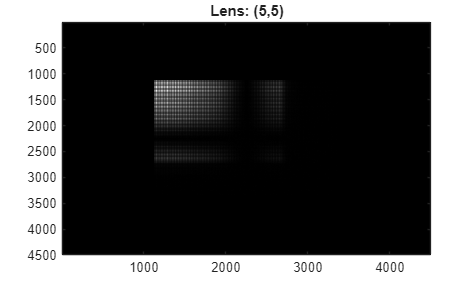

%% Use loaded ATF
% Load pupil func etc.
load('../atf.mat');
% load('../atf_fresnel.mat');

% convert
atf = permute(atf,[2,3,1]);

% show
figure;
for i=1:M
    for j=1:M
        index = sub2ind([M,M],i,j);
        imagesc(abs(atf(:,:,index)));colormap("gray");
        title(sprintf('Lens: (%d,%d)',i,j))
        drawnow
        pause(0.05)
    end
end

%% Use synthetic ATF
ratio = 0.5;
freq_cutoff = 0.5; % half of nyquist as ATF full support
M = 3;
sz = 300;
width = round(sz * ratio * freq_cutoff);
fprintf('Lens eff. size: %.0f px\n',width);

Lens eff. size: 75 px


fprintf('Lens eff. overlap: %.1f percent\n',(width/(sz/M)-1)*100);

Lens eff. overlap: -25.0 percent


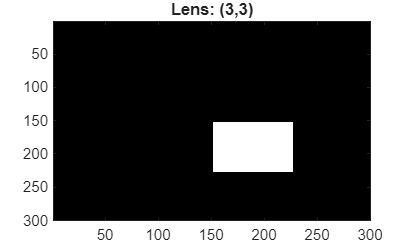

step = round((sz*freq_cutoff-width)/(M-1));
shift = floor(sz*freq_cutoff/2);
atf = zeros([sz,sz,M*M]);
figure;
for i=1:M
    for j=1:M
        index = sub2ind([M,M],i,j);
        atf0 = zeros(sz,sz);
        y_start = (i-1)*step +1 + shift;
        y_end = min([y_start+width-1,sz]);
        x_start = (j-1)*step +1 + shift;
        x_end = min([x_start+width-1,sz]);
        atf0(y_start:y_end,x_start:x_end) = 1;
        atf(:,:,index) = atf0;
        imagesc(atf0);colormap("gray");
        title(sprintf('Lens: (%d,%d)',i,j))
        drawnow
        pause(0.05)
    end
end

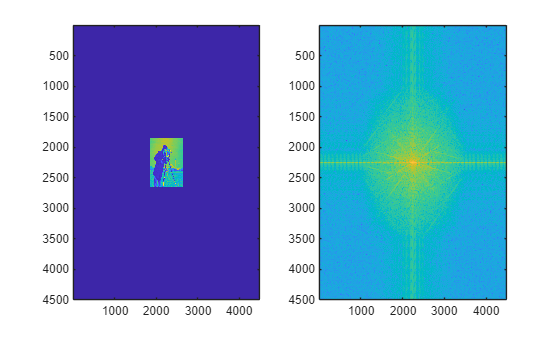


% load test image
im = imread('cameraman.tif');
im = rescale(imresize(im, [800,800]));
idx_start = floor((size(atf,1)-size(im,1)) / 2);
idx_end = idx_start + size(im,1) -1;
im_padded = zeros(size(atf,1),size(atf,2));
im_padded(idx_start:idx_end,idx_start:idx_end) = im;
im = im_padded;
figure
subplot(121)
imagesc(im)

% imaging simulation
spec = fftshift(fft2(ifftshift(im)));
subplot(122)
imagesc(pow2db(abs(spec).^2))

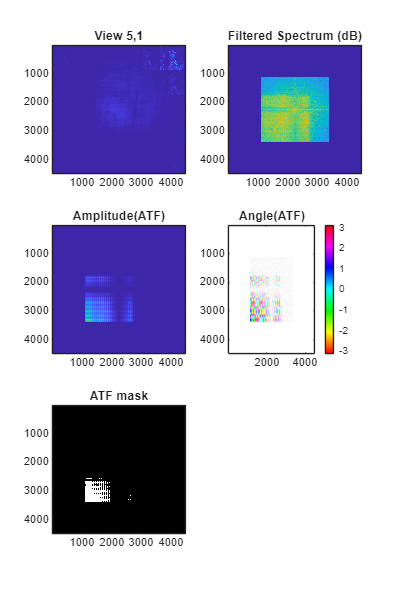


% apply ATF to data
spec_filtered = spec .* atf;
im_filtered = abs(ifftshift(ifft2(fftshift(spec_filtered))));

% prepare ATF amplitude mask
threshold = 0.2;
mask = rescale(abs(atf))>threshold;

% visualize filtered data
figure('Position',[100,100,400,600]);
for i=1:M
    for j=1:M
        lens_index = sub2ind([M,M],i,j);
        subplot(321)
        imagesc(im_filtered(:,:,lens_index))
        title(sprintf('View %d,%d',i,j))
        subplot(322)
        imagesc(pow2db(abs(spec_filtered(:,:,lens_index)).^2))
        title('Filtered Spectrum (dB)')
        subplot(323)
        imagesc(abs(atf(:,:,lens_index)))
        title('Amplitude(ATF)')
        subplot(324)
        alpha = rescale(abs(atf(:,:,lens_index))).^0.5;
        imagesc(angle(atf(:,:,lens_index)),'AlphaData',alpha);
        colorbar
        colormap(gca,hsv)
        title('Angle(ATF)')
        subplot(325)
        imagesc(mask(:,:,lens_index))
        colormap(gca,'gray')
        title('ATF mask')
        drawnow
        pause(0.1)
    end
end

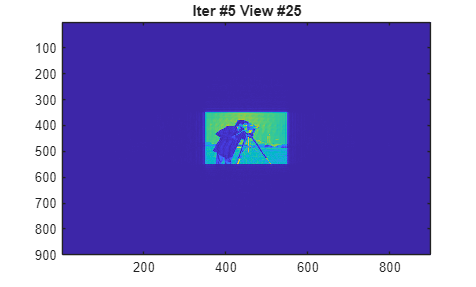

% iterative reconstruction
nIter = 5;
center_index = sub2ind([M,M],3,3);
im_recon = im_filtered(:,:,center_index);

figure;
for i=1:nIter
    % go through every view
    for j = 1:size(atf,3)
        % forward
        spec_recon = fftshift(fft2(ifftshift(im_recon)));
        spec_recon_fwd = spec_recon .* atf(:,:,j);
        im_recon_fwd = ifftshift(ifft2(fftshift(spec_recon_fwd)));
        % splite amp and phase for forwarded one
        amp_recon_fwd = abs(im_recon_fwd);
        phase_recon_fwd = angle(im_recon_fwd);

        % replace amp with measurement's for forwarded one
        im_recon_fwd = im_filtered(:,:,j) .* exp(1j*phase_recon_fwd);

        % backward use 1/atf
        spec_recon_bwd = fftshift(fft2(ifftshift(im_recon_fwd)));
        correction = atf(:,:,j);
        spec_recon_bwd(mask(:,:,j)) = spec_recon_bwd(mask(:,:,j))./correction(mask(:,:,j));
        

        % replace spectum with backward one within mask
        spec_recon(mask(:,:,j)) = spec_recon_bwd(mask(:,:,j));

        % re-compute to update
        im_recon = ifftshift(ifft2(fftshift(spec_recon)));

        % plot
        imagesc(abs(im_recon));
        title(sprintf('Iter #%d View #%d',i, j))
        drawnow
    end
    % % plot
    % imagesc(abs(im_recon));
    % title(sprintf('Iter #%d',i))
    % drawnow
    % pause(0.1)
end

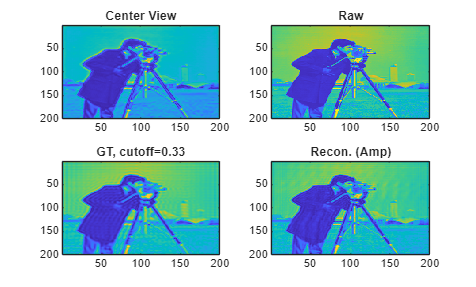


crop_sz = 200;
crop_idx = floor((size(im_recon,1) - crop_sz)/2):floor((size(im_recon,1) - crop_sz)/2)+crop_sz-1;
figure
subplot(221)
imagesc(im_filtered(crop_idx,crop_idx,center_index))
title('Center View')
subplot(222)
imagesc(im(crop_idx,crop_idx))
title('Raw')
subplot(223)
cutoff = 0.33;
spec = fftshift(fft2(ifftshift(im)));
y_idx = ceil(size(im,1)*(1-cutoff)/2):ceil(size(im,1)*(1+cutoff)/2);
x_idx = ceil(size(im,2)*(1-cutoff)/2):ceil(size(im,2)*(1+cutoff)/2);
mask_sup = true(size(spec));
mask_sup(y_idx,x_idx) = false;
spec(mask_sup) = 0;
im_supp = abs(ifftshift(ifft2(fftshift(spec))));
imagesc(im_supp(crop_idx,crop_idx))
title(sprintf('GT, cutoff=%.2f',cutoff))
subplot(224)
imagesc(abs(im_recon(crop_idx,crop_idx)))
title('Recon. (Amp)')